## SimpleSonarRange.mlx

is an example of rading an analog sonar on an Arduino

hook analog out from sesnor into Pin A2, Vcc to 5 VDC, and gnd to gnd.

Program collects range voltrage data, plots it, and is terminated by operator input.

Braden and Dowling, 2-23-23, Revision 0

clc                                     % clear command window
clear                                   % clear MATLAB workspace

## Set up robot control system (code that runs once)

% create arduino ref-objects
[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('/dev/cu.usbmodem14101', 'Uno');

% Turn on board LED on and off to signal program has started
Blink(robotArduino, blinkLED, 5);
disp('Warning! Data Collection Active!')

Warning! Data Collection Active!


nTests = input(['Enter number of range test postions, ' 'followed by enter: '])

nTests = 1

clc % clear command window

positionData = zeros(nTests, 2);

r = rateControl(0.1);   % create a 0.1 hz loop rate
reset(r);               % reset loop to time zero

## Run Robot Control Loop (code that runs over and over)

controlFlag = 1;                         % create a loop control
while (controlFlag < nTests+1)
    rangeData=SENSE(robotArduino, rawRangeIn)
    THINK();
    ACT();
    positionData(controlFlag, 1) = input('Enter actual distance (cm): ');
    gtest= input('moves Sonar to new range, type G, then hit ENTER','s');
    positionData(controlFlag, 2)=rangeData;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);
    controlFlag= controlFlag+1;
                            
end

Sense


rangeData = 0.1466

## Mission data processing 

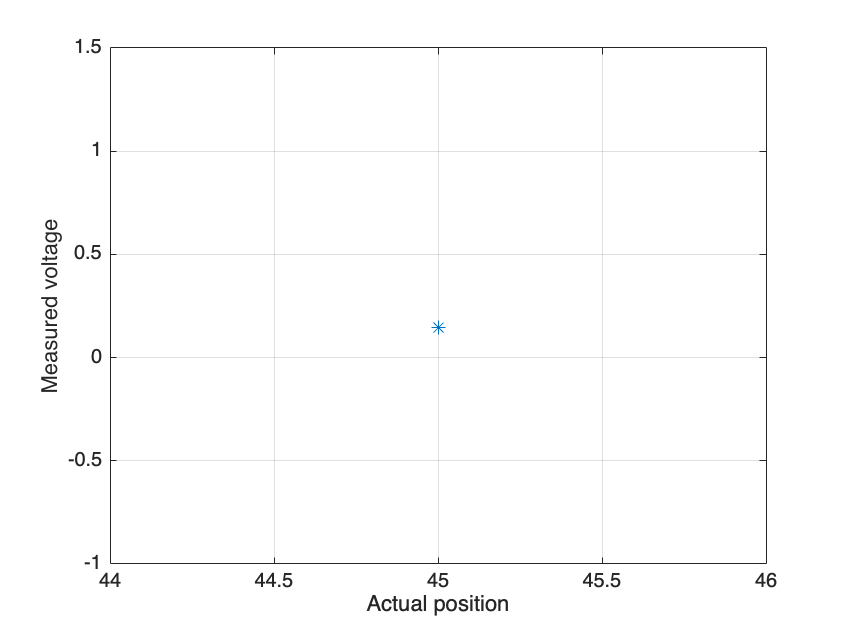

plot(positionData(:,1), positionData(:,2), '-*')
xlabel('Actual position')
ylabel('Measured voltage')
grid

## Clean shut down

clc
disp('Arduino program has ended');

Arduino program has ended


clear robotArduino
beep

## Robot Functions (store this codes local functions here)

In practice for modularity, readability and longiteveity, your main robot code should be as brief

as possible and the bulk of the work should be done by functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT, MODEL)
robotArduino = arduino(COMPORT, MODEL , 'Libraries', 'Servo');

% configure pin 13 as a digitial-out LED
blinkLED = 'D13';
configurePin(robotArduino, blinkLED, 'DigitalOutput');

% configure A0 pin as an analog input
rawRangeIn = 'A1';
configurePin(robotArduino, rawRangeIn, 'AnalogInput');
end

function [] = Blink(a,LED, n)
        for bIndex = 1:n
            writeDigitalPin(a, LED, 0);
            pause(0.2);
            writeDigitalPin(a, LED, 1);
            pause(0.2);
        end
end

## **Sense Functions (store all Snese related local functions here)**

function rangeData = SENSE(robotArduino, rawRangeIn)
    disp('Sense');
    rangeData = readVoltage(robotArduino, rawRangeIn);
end

## Think Function (store all Think related local functions here)

function THINK()
    
end

## Act Functions (store all Act related local functions here)

function ACT(time)
    

end